phi = 0;
W = 4;
D = 2;
L = 1;
rho_full = 1250;
rho_water = 1000;

disp_ratio = 0.25;
percent_infill = disp_ratio * (rho_water)/(rho_full);
f_rho_dynamic = @(y, h) ( (y >= h)*0.5*rho_full + (y < h)*rho_full );
f_rho_const = @(y, h) (percent_infill * rho_full);

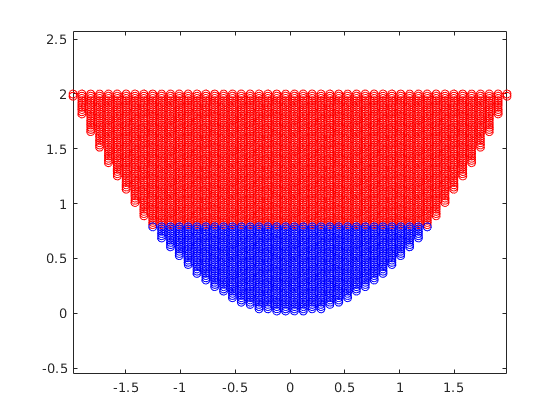

center_of_mass =     0.0000    1.2059


center_of_buoyancy =    -0.0000    0.4795


mass_boat = 1.3444e+03

mass_water = 1.3452e+03

f_contour_quadratic = @(x, y)(D * (2*x/W).^2 <= y);
[center_of_mass, center_of_buoyancy, mass_boat, mass_water] ...
    = boat_sim(phi, W, D, L, f_contour_quadratic, @(y) (f_rho_const(y, 0.2)), true)

f_contour_linear = @(x, y) (D * abs(2*x/W) <= y);

phis = 1:180;
moment_arms = zeros(size(phis));

for phi = phis
    moment_arms(phi) = f_moment_arm(phi, W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0)));
end

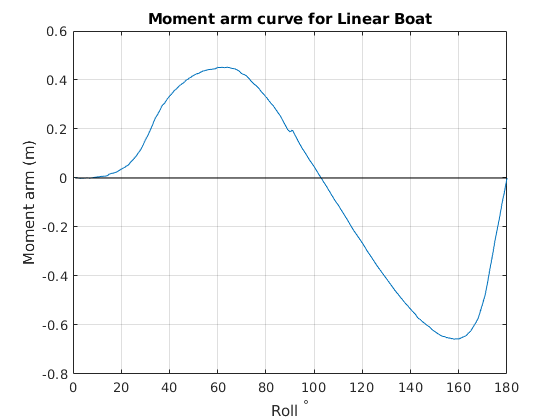

figure();
plot(phis, moment_arms);
line([min(phis), max(phis)], [0, 0], 'color', 'black')

grid on
title("Moment arm curve for Linear Boat")
xlabel("Roll ^\circ")
ylabel("Moment arm (m)")

avs = fzero(@(phi) (f_moment_arm(phi, W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0))) ), [10 175]);
disp(avs)

  102.9606



calc_avs(W, D, L, f_contour_linear, @(y)(f_rho_const(y, 0)))

ans = 102.9606

[min_params, max_avs] = fminsearch(@(params) (140 - calc_avs(params(1), params(2), L, f_contour_linear, @(y)(f_rho_const(y, 0)))), [4, 2] );

v_w = linspace(0.1, 8, 20);
v_d = linspace(0.1, 4, 20);
[mat_W, mat_D, mat_avs] = param_sweep(v_w, v_d, f_contour_quadratic, @(y)(f_rho_const(y, 0)));

i_max_avs = find(mat_avs == max(mat_avs, [], 'all'));
w_max = mat_W(i_max_avs);
d_max = mat_D(i_max_avs);
calc_avs(w_max, d_max, L, f_contour_quadratic, @(y) (f_rho_const(y, 0)))

ans = 162.9905

phis = 1:180;
moment_arms = zeros(size(phis));

for phi = phis
    moment_arms(phi) = f_moment_arm(phi, w_max, d_max, L, f_contour_quadratic, @(y)(f_rho_const(y, 0)));
end

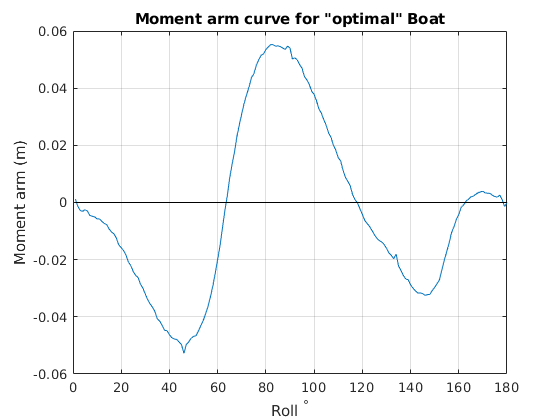

figure();
plot(phis, moment_arms);
line([min(phis), max(phis)], [0, 0], 'color', 'black')

grid on
title("Moment arm curve for ""optimal"" Boat")
xlabel("Roll ^\circ")
ylabel("Moment arm (m)")

function moment_arm = f_moment_arm(phi, W, D, L, f_contour, f_rho)
    [com, cob, ~, ~] = boat_sim(phi, W, D, L, f_contour, f_rho, false);
    moment_arm = com(1) - cob(1);
end

function avs = calc_avs(W, D, L, f_contour, f_rho)
    avs = fzero(@(phi) (f_moment_arm(phi, W, D, L, f_contour, f_rho)), [10 175]);
end

function [mat_W, mat_D, mat_avs] = param_sweep(v_w, v_d, f_contour, f_rho)
    [mat_W, mat_D] = meshgrid(v_w, v_d);
    
    v_points = [mat_W(:), mat_D(:)];
    v_avs = zeros(length(v_points), 1);
    L = 1;
    for i = 1 : length(v_points)
        try
            v_avs(i) = calc_avs(v_points(i, 1), v_points(i, 2), L, f_contour, f_rho);
        catch exception
            % Check for the case of undefined AVS
            if strcmp(exception.identifier, 'MATLAB:fzero:ValuesAtEndPtsSameSign')
                fprintf("AVS undefined at [w, d] = [%f, %f]\n", v_points(i, 1), v_points(i, 2));
                v_avs(i) = 0;
            else
                % Otherwise throw error
                throw(exception)
            end            
            
        end
    end
    mat_avs = reshape(v_avs, size(mat_W));
end